# Q1:

P = [0.9, 0.1; 0.48, 0.52];
answers.q1 = P;
disp(P);

    0.9000    0.1000
    0.4800    0.5200



## Q2:

answers.q2 = P^100;
disp(P^100);

    0.8276    0.1724
    0.8276    0.1724



## Q3:

pi0 = [1 0]; % Dry day
pi100_dry = pi0*P^100;
pi0 = [0 1]; % Wet day
pi100_wet = pi0*P^100;
disp(pi100_dry)

    0.8276    0.1724



disp(pi100_wet)

    0.8276    0.1724



## Q4:

[V, D] = eig(P');
answers.q4 = V;
disp(V);

    0.9790   -0.7071
    0.2040    0.7071



disp(D);

    1.0000         0
         0    0.4200



## Q5:

answers.q5 = V(:,1);
disp(V(:,1));

    0.9790
    0.2040



## Q6:

s = sum(V(:, 1));
disp(s);

    1.1829



## Q7:

vec =  V(:,1)/sum(V(:,1));
disp(vec)

    0.8276
    0.1724



## Q9:

P = [0.9, 0.10; 0.48, 0.52];
T = 365;
X = NaN(1,T);
X(1) = 1;
for i = 2:T
    probs = P(X(i-1),:);
    X(i) = binornd(1, probs(2))+1;
end
answers.q9 = X;
disp(answers.q9)

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     1     1     2     2     2     2     1     1     1     2     2     2     2     1     1     2     2     1     1     1     1     1     1     1     1     2     2     1     1     1     1     1     1     1     1     1     1     2     1     1     1     1     1     1     1     1     1     1     1     2     2     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     1     1     1     1     1     2     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     1     1     1     1     2     2     1     1     1     1     2     2     2     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     1     1     1     1     1    

## Q10:

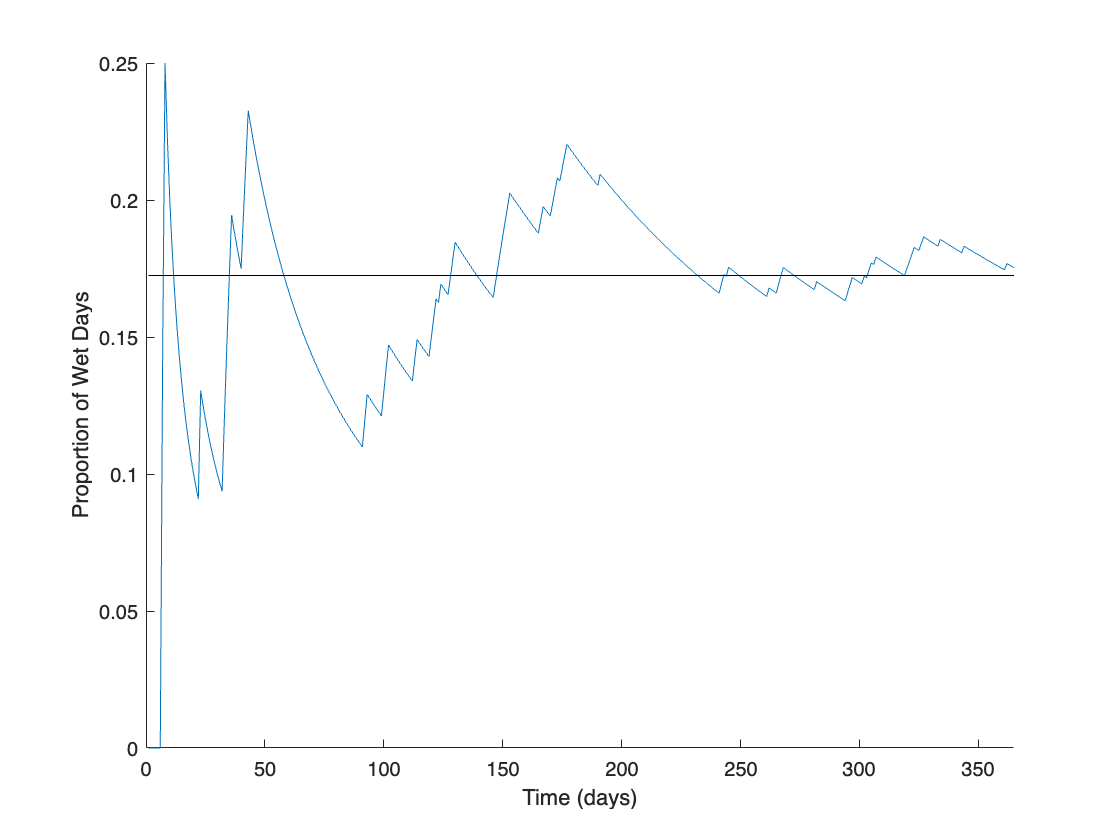

figure;
hold on
plot(1:T, cumsum(X-1)./(1:T))
plot([1, T], [vec(2), vec(2)], 'color', 'k')
xlabel('Time (days)')
xlim([0 T])
ylabel('Proportion of Wet Days')

## Q11a:

answers.q11a = [0.5, 0.5];


## Q11b:

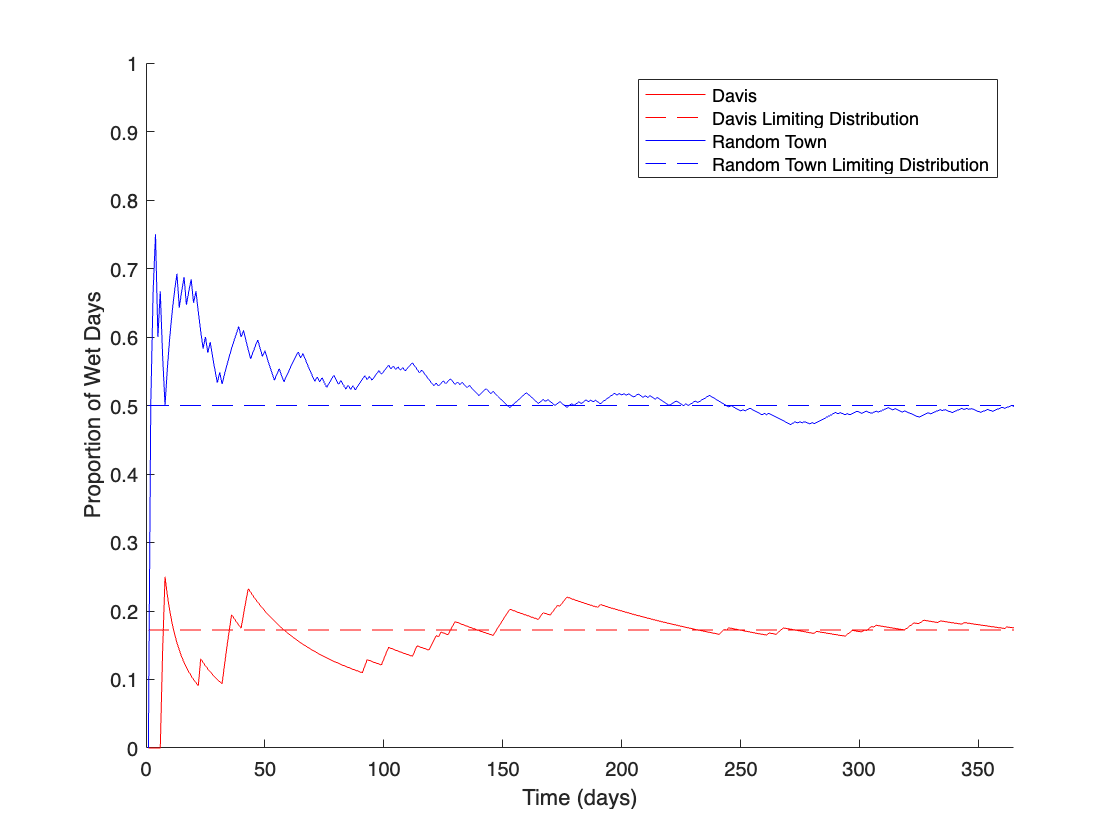

P2 = [0.5, 0.5; 0.5, 0.5];
X2 = NaN(1, T);
X2(1) = 1;
for i = 2:T
    probs = P2(X2(i-1),:);
    X2(i) = binornd(1, probs(2))+1;
end

figure;
hold on
plot(1:T, cumsum(X-1)./(1:T), 'r')
plot([1 T], [vec(2) vec(2)], '--r')
plot(1:T, cumsum(X2-1)./(1:T), 'b')
plot([1 T], [0.5 0.5], '--b')
xlabel('Time (days)')
xlim([0 365])
ylim([0 1])
ylabel('Proportion of Wet Days')
legend('Davis', 'Davis Limiting Distribution', ...
    'Random Town', 'Random Town Limiting Distribution')

## Q12

file = fastaread('Ecoli-k12-genome.fasta');
seq = file.Sequence;
 
di_nuc_counts = zeros(4);
 
for i = 1:length(seq)-1
    di_nuc = seq(i:i+1); % Read dinucleotide 
    row = nuc_to_index(di_nuc(1)); % Convert letters to index for matrix
    col = nuc_to_index(di_nuc(2)); % Convert letters to index for matrix
    di_nuc_counts(row, col) = di_nuc_counts(row, col) + 1;
end
transition_matrix = di_nuc_counts./sum(di_nuc_counts, 2);
disp(transition_matrix)

    0.2958    0.2712    0.2083    0.2247
    0.1858    0.2975    0.2824    0.2343
    0.2271    0.2172    0.2295    0.3262
    0.2757    0.2001    0.2939    0.2303



## Q13:

[V, ~] = eig(transition_matrix);
DNA_vec = V(:,1)/sum(V(:,1));
disp(DNA_vec)

    0.2500
    0.2500
    0.2500
    0.2500



## Q14:

file = fastaread('Organism_A.fasta');
seq = file.Sequence;
 
di_nuc_counts = zeros(4);
 
for i = 1:length(seq)-1
    di_nuc = seq(i:i+1); % Read dinucleotide 
    row = nuc_to_index(di_nuc(1)); % Convert letters to index for matrix
    col = nuc_to_index(di_nuc(2)); % Convert letters to index for matrix
    di_nuc_counts(row, col) = di_nuc_counts(row, col) + 1;
end
transition_matrix_A = di_nuc_counts./sum(di_nuc_counts, 2);


file = fastaread('Organism_B.fasta');
seq = file.Sequence;
 
di_nuc_counts = zeros(4);
 
for i = 1:length(seq)-1
    di_nuc = seq(i:i+1); % Read dinucleotide 
    row = nuc_to_index(di_nuc(1)); % Convert letters to index for matrix
    col = nuc_to_index(di_nuc(2)); % Convert letters to index for matrix
    di_nuc_counts(row, col) = di_nuc_counts(row, col) + 1;
end
transition_matrix_B = di_nuc_counts./sum(di_nuc_counts, 2);

answers.q14 = {transition_matrix_A, transition_matrix_B};

disp(transition_matrix_A);

    0.4513    0.0503    0.2490    0.2494
    0.0525    0.4392    0.2525    0.2558
    0.0981    0.1008    0.3996    0.4015
    0.1003    0.0991    0.3987    0.4019



disp(transition_matrix_B);

    0.2459    0.2506    0.2550    0.2486
    0.2528    0.2527    0.2457    0.2488
    0.0988    0.1008    0.3998    0.4005
    0.0984    0.1014    0.3990    0.4011



## Q15:

[VA, ~] = eig(transition_matrix_A');
[VB, ~] = eig(transition_matrix_B');

display(VA(:,1)/sum(VA(:,1)));

    0.1430
    0.1405
    0.3571
    0.3594



display(VB(:,1)/sum(VA(:,1)));

    0.1420
    0.1444
    0.3574
    0.3580



## function

function index = nuc_to_index(nuc)
 
switch nuc
    case {'A', 'a'}
        index = 1;
        return
    case {'T', 't'}
        index = 2;
        return
    case {'G', 'g'}
        index = 3;
        return
    case {'C', 'c'}
        index = 4;
        return 
end
end